clc; clear; close all;

# Loading Data

C = 27;

# Convergence on Unit Square

I do this because then we can look at performance without the need of interpolation onto a Cartesian Grid, using the same function still works for this purpose. We just let M_p(xi, eta) = (x, y)

n_values = [50, 75, 100, 125, 150, 200, 225, 250, 275, 300, 400];
d_values = 3:10;

err_values = zeros(length(n_values), length(d_values));
order_values = zeros(length(n_values), length(d_values));
for d_idx = 1:length(d_values)
    d = d_values(d_idx);
    
    load(['FC_data/A_d',num2str(d),'_C', num2str(C), '.mat']);
    load(['FC_data/Q_d',num2str(d),'_C', num2str(C), '.mat']);
    A = double(A);
    Q = double(Q);
    for n_idx =1:length(n_values)
        % creating unit square
        n_eta = n_values(n_idx);
        n_xi = n_values(n_idx);
        h_eta = 1/(n_eta-1);
        h_xi = 1/(n_xi-1);
        
        xi_mesh = transpose(linspace(0, 1, n_xi));
        eta_mesh = transpose(linspace(0, 1, n_eta));
        [XI, ETA] = meshgrid(xi_mesh, eta_mesh);
        
        % function values in unit square
        f_xy = f(XI, ETA);
        
        % FC for C2 type patch
        fcont = fcont_gram_blend_C2(f_xy, d, A, Q);
        cont_eta_mesh = transpose(-C*h_eta:h_eta:1);
        cont_xi_mesh = transpose(-C*h_eta:h_eta:1);
        n_cont = n_xi+C;
            
        % FC fft coefficients
        fc_coeffs = fft2(fcont)/numel(fcont);
        
        % computing error on mesh 5 times finer
        n_err_mesh = 5*n_cont; % relative to [0, 1]
        
        [Q_shift, P_shift] = meshgrid(0:(n_err_mesh - 1));
        shift_matrix = exp(-2i*pi*floor(n_cont/2)*P_shift/n_err_mesh) .* exp(-2i*pi*floor(n_cont/2)*Q_shift/n_err_mesh);
        f_numeric = real(n_err_mesh^2*ifft2(fftshift(fc_coeffs), n_err_mesh, n_err_mesh).*shift_matrix);
        
        % isolating interior
        err_mesh = transpose(linspace(-C*h_eta, 1+h_eta, n_err_mesh+1));
        err_mesh = err_mesh(1:end-1);
        [XI_ERR, ETA_ERR] = meshgrid(err_mesh);
        omega_msk = XI_ERR <= 1 & XI_ERR >= 0 & ETA_ERR <= 1 & ETA_ERR >= 0;
        err_values(n_idx, d_idx) = max(abs(f_numeric(omega_msk)-f(XI_ERR(omega_msk), ETA_ERR(omega_msk))));
        
        % computing numeric order
        if n_idx > 1
            order_values(n_idx, d_idx) = log2(err_values(n_idx-1, d_idx)/err_values(n_idx, d_idx));
        end
    end
end

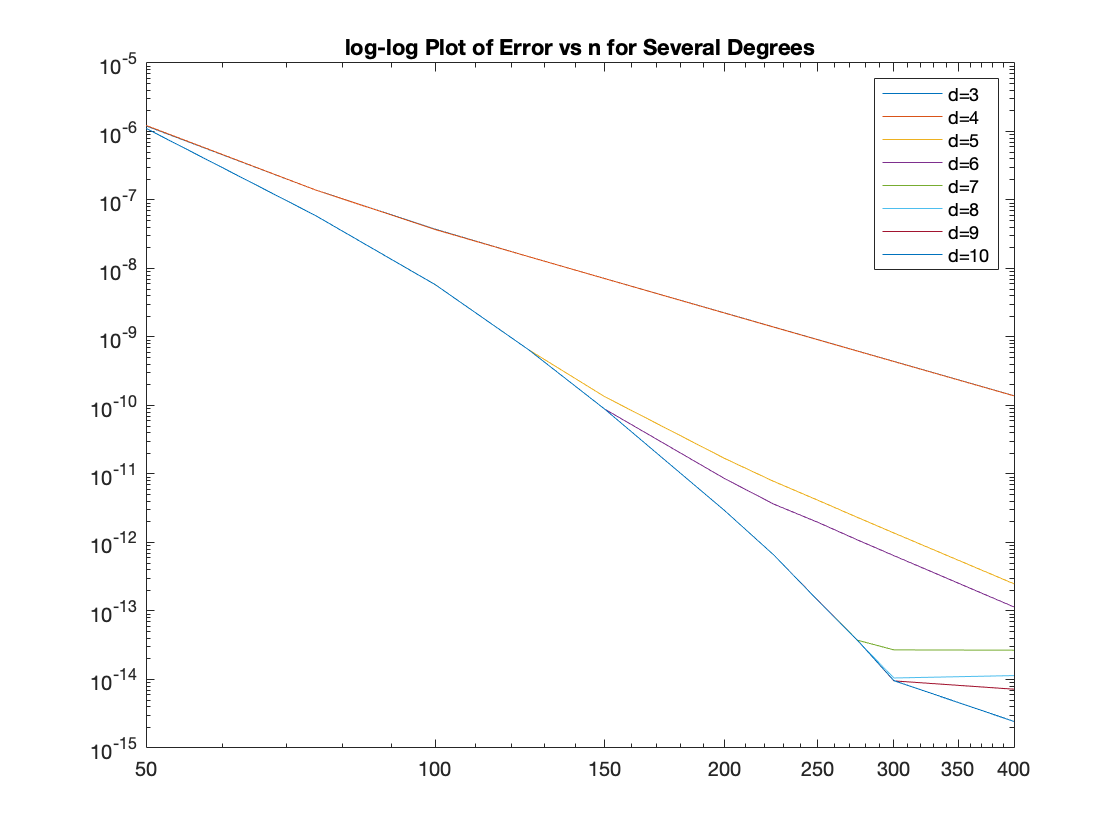

%disp(order_values)

figure;
loglog(n_values, err_values)
title("log-log Plot of Error vs n for Several Degrees")
d_legend = cellstr(num2str(d_values', 'd=%-d'));
legend(d_legend)


err_values

err_values = 	1.0e+-5 *

    0.1210    0.1227    0.1112    0.1112    0.1112    0.1112    0.1112    0.1112
    0.0141    0.0141    0.0060    0.0060    0.0060    0.0060    0.0060    0.0060
    0.0037    0.0037    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006
    0.0015    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0007    0.0007    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0002    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


# Convergence on General C2 Patch

n_eta = 50;
n_xi = 50;
h_eta = 1/(n_eta - 1);
h_xi = 1/(n_xi - 1);

n_theta = 10*n_eta; % number of discretization points of boundary, in this test is just a function of n_eta
theta_mesh = transpose(linspace(0, 2*pi, n_theta));

% boundary parameterization in terms of theta (polar coordinates)
l_theta = @(theta) [2*sin(theta/2), -sin(theta)];
boundary_xy = l_theta(theta_mesh);

% thetas of each corner
theta_a = theta_mesh(n_xi);
theta_b = theta_mesh(end-n_eta+1);
theta_c = 0;

% parameter mapping, as defined in Leibovici
l_A = @(xi) xi*(theta_a);
l_B = @(eta) eta*(theta_b-2*pi) + 2*pi;
M_p = @(xi, eta) l_theta(l_A(xi)) + l_theta(l_B(eta)) - l_theta(theta_c);

% eta and xi meshes
eta_mesh = transpose(linspace(0, 1, n_eta));
xi_mesh = transpose(linspace(0, 1, n_xi));

[ETA, XI] = meshgrid(eta_mesh, xi_mesh);
corner_xy = M_p(XI(:), ETA(:)); % x-y values mapped from xi-eta unit square
f_xy = reshape(f(corner_xy(:, 1), corner_xy(:, 2)), size(ETA)); % values of f on xi-eta unit square

fcont = fcont_gram_blend_C2(f_xy, d, A, Q); % FC for C2 type patch
cont_eta_mesh = transpose(-C*h_eta:h_eta:1); % continued meshes
cont_xi_mesh = transpose(-C*h_eta:h_eta:1);

% for cartesian grid, use h_theta as h_grid
%n_grid = n_eta+n_xi;

% very smooth piecewise function being used for testing, vanishes on and
% outside circle of radius 0.56, chosen so 2D-FC for C2 type patches makes
% patch biperiodic
function f_y = f(x, y)
    r = sqrt(x.^2 + y.^2);
    f_y = zeros(size(x));
    f_y(r < 0.56) = exp(1./(1/0.56*r(r < 0.56).^2-0.56));
    f_y(r >= 0.56) = 0;
end